# Practical Assignment 1: Accoustic localisation

Names:

NetIDs:

clear; clf; clc; close all;
addpath data
addpath functions

## 1. Calibration

load('calibration.mat')


### a) Measurement errors of each microphone at each sound pulse

**Your text here** (*Please you the equation editor for equations)* **:**


% For this calibration it is assumed that the average TOA at each time step is
% exactly the correct TOA

TOA_avg = zeros(59,1);
meas_errors = zeros(59,8);
biases = zeros(8,1);
vars = zeros(8,1);

for k = 1:59
    TOA_avg(k) = sum(y_toa(k,1:8))/8;
end

% calculate the measurement error per timestep k for each
% microphone

for i = 1:8
    meas_errors(:,i) = y_toa(:,i) - TOA_avg;
end


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**

% calculate the bias from the measuremnt error per time step for
% each microphone. The bias is the mean of the measurement errors.


for i = 1:8
    biases(i) = mean(meas_errors(:,i));
end


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

**Your text here** (*Please you the equation editor for equations)* **:**

% calculate the variance of the measurement errors for each
% microphone

for i = 1:8
    vars(i) = var(meas_errors(:,i));
end



Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

Uncomment the code sniplet below.

**Your text here:**

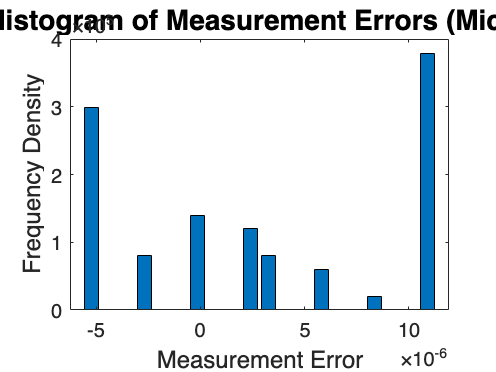

% make a histogram of the measurement errors of microphone 1
% figure(1); clf;
% for i = 1:size(y_toa,2)
%      subplot(4,2,i);
%      [N, l] = hist(meas_errors(:,i),20);
%      Wb     = l(2)-l(1); % Bin widths
%      Ny     = length(meas_errors(:,i)); % Nr of samples
%      bar(l, N);
%      title(['mic number: ',num2str(i)],'Interpreter','Latex','Fontsize',14)
% end

% make a histogram of the measurement errors of microphone 1
% [N, l] = hist(meas_errors(:,1),20);
% Wb=l(2)-l(1); % Bin width
% Ny = length(meas_errors(:,1)); % Nr of samples
% bar(l, N/(Ny*Wb));
% 
% figure; histfit(meas_errors(:,1));


figure;
[N, l] = hist(meas_errors(:,1),20);
Wb = l(2) - l(1); % bin width
Ny = length(meas_errors(:,1)); % bumber of samples
bar(l, N/(Ny*Wb));
xlabel('Measurement Error', 'Fontsize', 12);
ylabel('Frequency Density', 'Fontsize', 12);
title('Histogram of Measurement Errors (Mic 1)', 'Fontsize', 14);

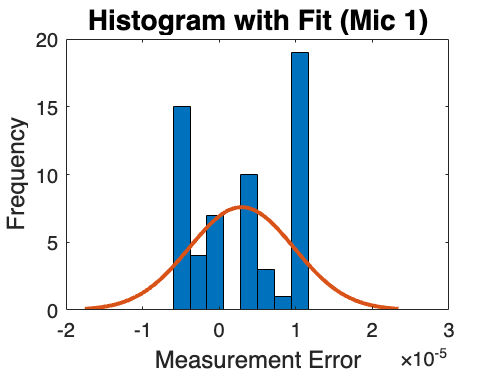


% Overlay a distribution fit
figure;
histfit(meas_errors(:,1));
xlabel('Measurement Error', 'Fontsize', 12);
ylabel('Frequency', 'Fontsize', 12);
title('Histogram with Fit (Mic 1)', 'Fontsize', 14);

## 2. Nonlinear least squares

load('experiment1.mat')

Error using load
experiment1.mat is not found in the current folder or on the MATLAB path, but exists in:
    /Users/kingekeulen/Documents/Systems and Control /Filtering and Identification Q2/Practical 1/data

Change the MATLAB current folder or add its folder to the MATLAB path.

load('ground_truth1.mat')




### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**


$$f=\tau_k +\frac{1}{c}\sqrt{{\left(x_k -M_x \right)}^2 +{\left(y_k -M_y \right)}^2 }$$



$$\begin{array}{l}
\textrm{Cov}\;\textrm{matrix}\;\textrm{is}\;a\;8\textrm{x8}\;\textrm{matrix}\;\to \\
\Sigma =\textrm{Cov}\left(\theta_{\textrm{hat}} \right)={\left(F^T \textrm{WF}\right)}^{-1} \\
W=\textrm{Weight}\;\textrm{matrix}\\
F\;=\textrm{Jacobian}\;\textrm{Matrix}
\end{array}$$


### b) Jacobian

**Your text here** (*Please you the equation editor for equations)* **:**


$$\left\lbrack \begin{array}{ccc}
\frac{\hat{x_k } -m_{x,1} }{c\left\|{\hat{p} }_k^i -m_1 \right\|} & \frac{{\hat{y} }_k -m_{y,1} }{c\left\|{\hat{p} }_k^i -m_1 \right\|} & 1\\
\vdots  & \vdots  & \vdots \\
\frac{\hat{x_k } -m_{x,8} }{c\left\|{\hat{p} }_k^i -m_8 \right\|} & \frac{{\hat{y} }_k -m_{y,8} }{c\left\|{\hat{p} }_k^i -m_8 \right\|} & 1
\end{array}\right\rbrack$$


### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@f,"2a1"))
disp(testmyresult(@Jacobian,"2a2"))

### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 100;             % maximum number of iterations
%disp(ones(3, maxiter))
stds = sqrt(var(meas_errors, 1));   % Standard deviations
y_calib = y_toa - ones(size(y_toa)) * diag(biases);
R = cov(meas_errors);
disp(R)

   1.0e-10 *

    0.4653   -0.0390    0.4653   -0.1592   -0.1291   -0.2093   -0.2131   -0.1810
   -0.0390    0.4484   -0.0390   -0.2353    0.2681    0.0301   -0.1990   -0.2345
    0.4653   -0.0390    0.4653   -0.1592   -0.1291   -0.2093   -0.2131   -0.1810
   -0.1592   -0.2353   -0.1592    0.3583   -0.2112   -0.0916    0.1902    0.3079
   -0.1291    0.2681   -0.1291   -0.2112    0.4184    0.1383   -0.1509   -0.2044
   -0.2093    0.0301   -0.2093   -0.0916    0.1383    0.4052    0.0108   -0.0743
   -0.2131   -0.1990   -0.2131    0.1902   -0.1509    0.0108    0.3526    0.2225
   -0.1810   -0.2345   -0.1810    0.3079   -0.2044   -0.0743    0.2225    0.3448





for k = 1:size(y_toa, 1)
    [th_nls(k, :), P_nls(:, :, k)] = NLS(y_calib(k, :), stds, th0, maxiter, mic_locations);
end

disp('Final Estimates:');

Final Estimates:


disp(th_nls);

    0.8052    0.0029    0.0773
    0.7289    0.0061    0.5888
    0.6642    0.0005    1.1003
    0.5934    0.0086    1.6118
    0.5225    0.0160    2.1232
    0.4568    0.0229    2.6347
    0.3841    0.0398    3.1462
    0.2415    0.0302    3.6576
    0.1642    0.0863    4.1691
    0.1253    0.1331    4.6806
    0.0826    0.2938    5.1922
    0.0628    0.3617    5.7037
    0.0415    0.4291    6.2151
    0.0328    0.4901    6.7266
    0.0386    0.5555    7.2381
    0.0387    0.6223    7.7496
    0.0898    0.7233    8.2612
    0.1122    0.8448    8.7725
    0.1536    0.8914    9.2840
    0.3011    0.9241    9.7956
    0.3643    0.9309   10.3071
    0.4970    0.9006   10.8185
    0.5404    0.8537   11.3300
    0.6114    0.7108   11.8415
    0.6311    0.6884   12.3530
    0.6494    0.6637   12.8644
    0.7088    0.6106   13.3759
    0.7121    0.6007   13.8874
    0.7164    0.5790   14.3989
    0.7829    0.6088   14.9104
    0.8771    0.6583   15.4220
    1.0291    0.6823   15.9334
    1.14

disp(P_nls)


(:,:,1) =

   1.0e-05 *

    0.1276   -0.0085   -0.0001
   -0.0085    0.1558    0.0002
   -0.0001    0.0002    0.0000


(:,:,2) =

   1.0e-05 *

    0.1175    0.0004   -0.0000
    0.0004    0.1669    0.0002
   -0.0000    0.0002    0.0000


(:,:,3) =

   1.0e-05 *

    0.1135    0.0031   -0.0000
    0.0031    0.1769    0.0002
   -0.0000    0.0002    0.0000


(:,:,4) =

   1.0e-05 *

    0.1133    0.0040   -0.0000
    0.0040    0.1742    0.0002
   -0.0000    0.0002    0.0000


(:,:,5) =

   1.0e-05 *

    0.1170    0.0070    0.0000
    0.0070    0.1644    0.0002
    0.0000    0.0002    0.0000


(:,:,6) =

   1.0e-05 *

    0.1244    0.0146    0.0000
    0.0146    0.1550    0.0002
    0.0000    0.0002    0.0000


(:,:,7) =

   1.0e-05 *

    0.1363    0.0308    0.0001
    0.0308    0.1540    0.0002
    0.0001    0.0002    0.0000


(:,:,8) =

   1.0e-05 *

    0.1832    0.0922    0.0003
    0.0922    0.2134    0.0003
    0.0003    0.0003    0.0000


(:,:,9) =

   1.0e-05 *

    0.1938    

### e) Visualisation and interpretation

Uncomment the code below.

**Your text here****:**

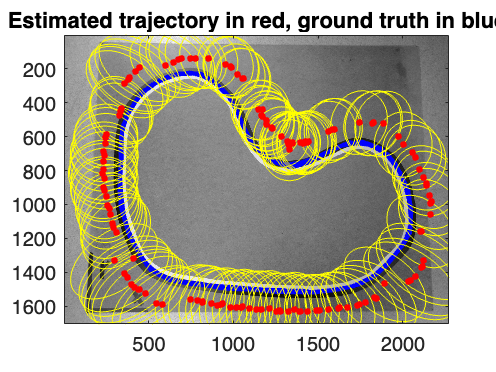



figure(2); clf;
plotresults(th_nls(:, 1:2)', P_nls(1:2,1:2,:), mic_locations', ground_truth);



% trajEst = th_nls(:, 1:2)'; % Extract the estimated trajectory (transpose to 2xN)
% P_diag = P_nls(1:2, 1:2, :); % Extract the 2x2 covariance matrices
% micPos = mic_locations'; % Transpose microphone positions to 2xN
% groundTruth = ground_truth(:, 1:2)'; % Extract and transpose ground truth positions
% 
% % Call the function
% plotresults(trajEst, P_diag, micPos, groundTruth);



## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_kf,"3a1"))

correct


disp(testmyresult(@timeupdate_kf,"3a2"))

correct


### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

In general,  a smaller Q implies a smoother trajectory but less adaptability to changes. Smaller R values imply high trust in the measurements but amplifies the influence of noise in the measurements. Larger R smoothens the estimates but may lag behind rapid changes.

The robots' position change will be bound by 0.01 m. This matches the constraints of the robot's movement and observations from the given video. Since 99.7% of Gaussian values fall within $$\pm 3\sigma$,$, we can define $$\sigma\ =\ \frac{0.01}{3}\ = 0.00333$$. Then the variance is computed, $$\sigma^2 \approx\ 1.11\ 10^-5$$. This results in a process covariance matrix of:


$$\left\lbrack \begin{array}{cc}
1\ldotp 11*{10}^{-5}  & 0\\
0 & 1\ldotp 11*{10}^{-5} 
\end{array}\right\rbrack$$


This relatively small scaling factor ensures that the Kalman filter relies primarily on the model over extended periods, while still allowing for small, realistic corrections based on the measurements. To determine appropriate values for R, the pseudo-measurements from question 2 were used. Since these pseudo-measurements are not entirely accurate, R was carefully tuned to better reflect their uncertainty.

Since the microphones are assumed to have independent noise characteristics, the matrix  R is diagonal. This simplification assumes there is no correlation between the measurement noise of different microphones.



p_0 = [0.12; 0.8]; % initial state mean
P_0 = eye(2); % initial covariance matrix
Q = 10^-5 * [1.05 0; 0 1.05]; % process noise covariance
R = 10^-3 * [8 0; 0 8]; % measurement noise covariance based on pseudo-meas from A2

scaler=10;
scaleFactor = P_nls(1,1)/scaler';
%Q = (scaleFactor)*eye(2)
%R = P_nls(1,1)*eye(2);
y = th_nls(:, 1:2)'; % Mmeasurements (positions)

% Kalman Filter
[trajEst, P_kal] = KF(p_0, P_0, R, Q, y);



### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

**Your text here:**

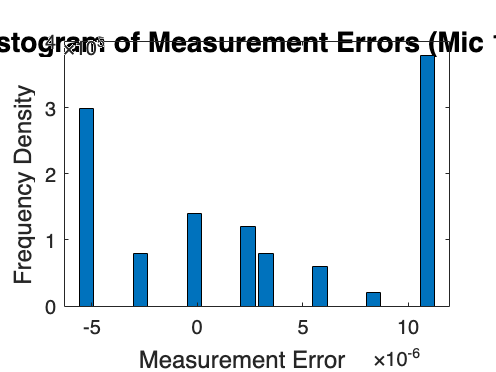

%P_kal(:, :, k) = P_k; % Store the covariance matrix for each time step
%disp(size(P_kal)); 


figure(3); clf;
plotresults(trajEst, P_kal, mic_locations',ground_truth);

% figure
% micPos = mic_locations';
% plotresults(trajEst,diagP,micPos)

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_ekf,"4a1"))

correct


disp(testmyresult(@timeupdate_ekf,"4a2"))

correct


### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

**EXPLAIN choice of Q!!**

delta_tau_d = diff(y_toa(:, 1));
delta_tau = mean(delta_tau_d);

d_tau_k = TOA_avg(2:end) - TOA_avg(1:end-1); % Differences in consecutive TOA averages
d_tau = mean(d_tau_k);                      % Mean difference (average step size)
sigma_tau = sqrt(sum((d_tau_k - d_tau).^2, 1) / (length(d_tau_k) - 1)); % Standard deviation
scaler = 3;
scaleFactor = P_nls(1,1)/scaler'

scaleFactor = 4.2539e-07


%Initialisation
delta_tau = 0.5115; % Fixed time step
Q0  = blkdiag(scaleFactor*eye(2),sigma_tau^2); % Process noise covariance init
%Q = blkdiag(5e-7, 5e-7, 5e-8); % Process noise covariance (tuned for smoothness and adaptability)
R = diag(stds.^2); % Measurement noise covariance (based on pseudo-measurements)

% start state and covariance
th_0 = [0.1; 0.6; 0]; % Init position and time offset
P_0 = diag([1, 1, 0.01]); % Init cov

% measurement data.
y = y_calib'; 
num_steps = size(y, 2);

% EKF function 
[th_ekf, P_ekf] = EKF(th_0, P_0, y, mic_locations, R, Q0);


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

**Your text here:**

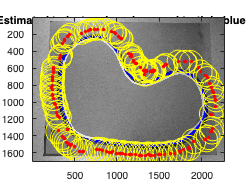

figure(4); clf;
plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

NLS

function [th_hat, P_hat] = NLS(yk, stds, th0, maxiter, mic_locations)
    % INPUT: 
    % yk               kth measurement (1x8 vector)
    % stds             standard deviations of measurement noise
    % th0              initial estimate (3x1 vector: [x, y, tau])
    % maxiter          maximum number of iterations 
    % mic_locations    microphone locations (8x2 matrix)

    % OUTPUT    
    % th_hat           mean of kth NLS estimate (3x1 vector)
    % P_hat            covariance matrix of kth NLS estimate (3x3 matrix)

  
    c = 343; % speed of sound in m/s

    % init variables
    th_hat = zeros(3, maxiter + 1); % storage for intermediate estimates
    th_hat(:, 1) = th0;             % set the initial estimate
    W = diag(1 ./ stds.^2);         % weight matrix
    e_update = 0;                   % previous error initialisation

    % iterative NLS estimation
    for i = 1:maxiter
        % predicted measurements f(\theta)
        distances = vecnorm(mic_locations' - th_hat(1:2, i)); % distances to microphones
        ftheta = th_hat(3, i) + distances' / c;              % predicted time of arrival (TOA)

        % compute the error
        e_new = yk(:) - ftheta(:);

        % Check for convergence
        if norm(e_update - e_new) < 1e-6 || i == maxiter
            % Compute the covariance matrix
            P_hat = inv(F' * W * F);
            th_hat = th_hat(:, i); % Return the final estimate
            return;
        end

        % compute the Jacobian matrix F
        F = zeros(size(mic_locations, 1), 3); % 8x3 Jacobian matrix
        for m = 1:size(mic_locations, 1) % loop through each microphone (8)
            dx = th_hat(1, i) - mic_locations(m, 1);
            dy = th_hat(2, i) - mic_locations(m, 2);
            distance = sqrt(dx^2 + dy^2);

            % Derivatives of f with respect to x, y, and tau
            F(m, 1) = (1 / c) * (dx / distance); % partial deriv w.r.t. x
            F(m, 2) = (1 / c) * (dy / distance); % partial deriv w.r.t. y
            F(m, 3) = 1;                         % partial deriv w.r.t. tau
        end

        % update the parameter estimate
        dTh = (F' * W * F) \ (F' * W * e_new); % Parameter update step
        th_hat(:, i + 1) = th_hat(:, i) + dTh; % Update estimate

        e_update = e_new;
    end
end


KF

function [trajEst, P_kal] = KF(p_0,P_0,R,Q,y)
    % INPUT: 
    % p_0       prior mean
    % P_0       prior covariance matrix
    % R         Measurement noise covariance matrices for k = 1,...,137
    % Q         Process noise covariance matrix
    % y         Measurements for k = 1,...,137
    % OUTPUT    
    % p_kf      Mean of the filtered distribution for every k
    % P_kf      Covariance matrix of the filtered distribution for every k
    
    % extract the num of time steps
    num_steps = size(y, 2);

    % initialise variables for storing results
    trajEst = zeros(size(p_0, 1), num_steps); % trajectory estimates
    P_kal = zeros(size(P_0, 1), size(P_0, 2), num_steps); % covariance matrices

    p_k = p_0; % Initial mean
    P_k = P_0; % Initial covariance

    % Kalman filter loop
    for k = 1:num_steps
        % time Update (Prediction)
        [p_k_pred, P_k_pred] = timeupdate_kf(p_k, P_k, Q);

        % measurement Update
        y_k = y(:, k); % current measurement
        [p_k, P_k] = measupdate_kf(p_k_pred, P_k_pred, R, y_k);

        trajEst(:, k) = p_k; % store the mean
        P_kal(:, :, k) = P_k; % store the covariance matrix 
    end
end

EKF

function [th_ekf,P_ekf] = EKF(th_0,P_0,y,mic_locations,R,Q)
    % INPUT 
    % th_0              prior mean
    % P_0               prior covariance matrix
    % y                 measurements for k = 1,...,137
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % Q                 process noise covariance matrix
        
    % OUTPUT    
    % th_ekf            mean of the filtering distribution for every k
    % P_ekf             covariance matrix of the filtering distribution for every k
    
    num_steps = size(y, 2); % num of time steps

    % initialise storage
    th_ekf = zeros(size(th_0, 1), num_steps);
    P_ekf = zeros(size(P_0, 1), size(P_0, 2), num_steps);

    % initial state
    th_k = th_0;
    P_k = P_0;

    % Extended Kalman Loop
    for k = 1:num_steps-1
        % time Update
        [th_pred, P_pred] = timeupdate_ekf(th_k, P_k, Q);

        % measurement Update
        y_k = y(:, k+1);
        [th_k, P_k] = measupdate_ekf(th_pred, P_pred, y_k, mic_locations, R);

        % store our results
        th_ekf(:, k+1) = th_k;
        P_ekf(:, :, k+1) = P_k;
    end

    % finally, include initial values in the results
    th_ekf(:, 1) = th_0;
    P_ekf(:, :, 1) = P_0;

    
end



